# Pro 2D bez zavazi

syms M I L x(t) y(t) fi(t) F1 F2 g

%kneticka energie kvadrokoptery
% translacni pohyb
W1 = 1/2*M*diff(x, 1)^2 % ve smeru x

$$W1(t) = \frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

W2 = 1/2*M*diff(y, 1)^2 % ve smeru y

$$W2(t) = \frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}$$

% rotacni pohyb
W3 =1/2*I*diff(fi, 1)^2

$$W3(t) = \frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}$$

T = W1+W2+W3;

%potencialni energie kvadrokoptery
V = M*g*y

$$V(t) = M\,g\,y\left(t\right)$$


%Lagrangian
Lag = T - V

$$Lag(t) = \frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}+\frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}-M\,g\,y\left(t\right)$$


%rovnice podle x
Qx = -(F1+F2)*sin(fi); %zobecnene sily podel x (nepotencialni)
eq1 = diff( diff(Lag, diff(x,1)), 1) - diff(Lag, x) == Qx

$$eq1(t) = M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$


%rovnice podle y
Qy = (F1+F2)*cos(fi); %zobecnene sily podel y (nepotencialni)
eq2 = diff( diff(Lag, diff(y,1)), 1) - diff(Lag, y) == Qy

$$eq2(t) = M\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+M\,g=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)$$


%rovnice podle fi
Qfi = (F1-F2)*L

$$Qfi = L\,\left(F_{1}-F_{2}\right)$$

eq3 = diff( diff(Lag, diff(fi,1)), 1) - diff(Lag, fi) == Qfi

$$eq3(t) = \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)$$


disp("---------------------------------------------------")

---------------------------------------------------


disp("---------------------------------------------------")

---------------------------------------------------


# Pro 2D se zavazim

syms x(t) y(t) fi(t) xp(t) yp(t) alfa(t)
syms M m F1 F2 k kp g F_wind d L I Ip

**Kineticka energia kvadrokoptery**

w_kin1 = 1/2*M*diff(x, 1)^2 %ve smeru x

$$w\_kin1(t) = \frac{M\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{2}$$

w_kin2 = 1/2*M*diff(y, 1)^2 %ve smeru y

$$w\_kin2(t) = \frac{M\,{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}}{2}$$

w_kin3 = 1/2*I*diff(fi, 1)^2 %rotacni pohyb

$$w\_kin3(t) = \frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}$$

**Kineticka energie zavazi**

xp = x+d*sin(alfa) %poloha teziste zavazi xp (zavisla promenna)

$$xp(t) = x\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)$$

yp = y-d*cos(alfa) %poloha teziste zavazi yp (zavisla promenna)

$$yp(t) = y\left(t\right)-d\,\cos\left(\mathrm{alfa}\left(t\right)\right)$$


%rychlosti 
vpx = diff(xp, 1) 

$$vpx(t) = \frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)$$

vpy = diff(yp, 1)

$$vpy(t) = \frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)$$

%celkovy vektor rychlosti

vp = sqrt(vpx^2 + vpy^2)

$$vp(t) = \sqrt{{\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}}$$

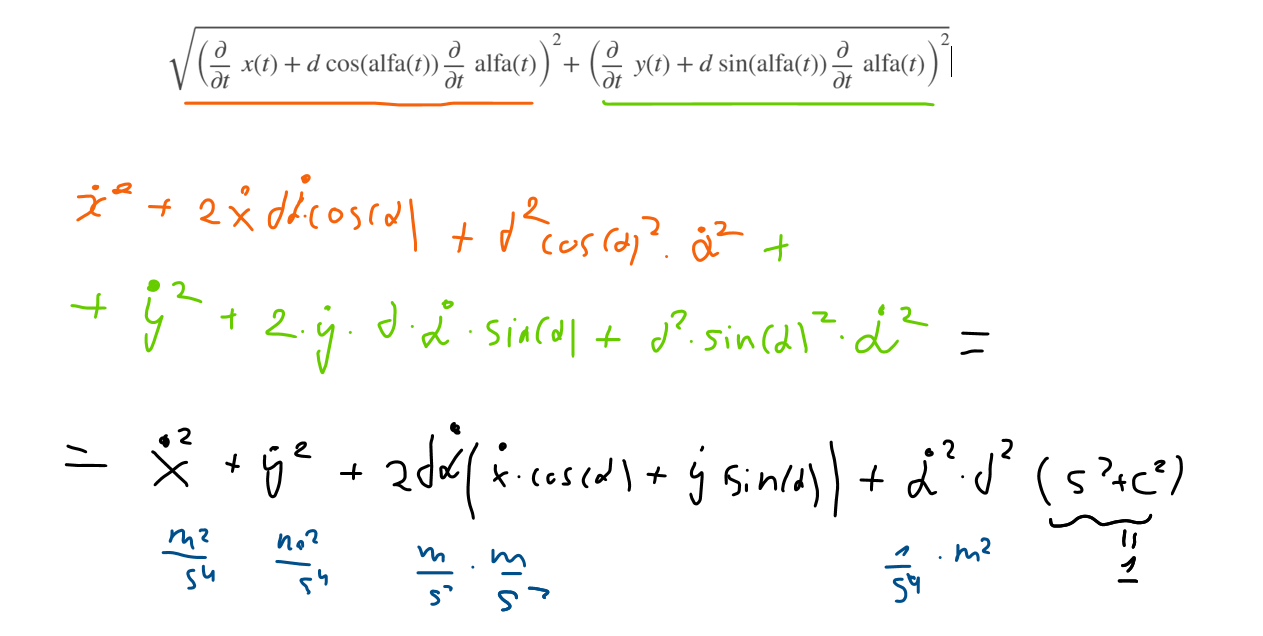

% |
% |
% V
% Vlastnorucne zjednoduseny tvar
vp = sqrt(simplify(expand(vpx^2 + vpy^2)))

$$vp(t) = \sqrt{{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+d^{2}\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)}$$


%kineticka energie zavazi
w_kin4 = 1/2*m*vp^2

$$w\_kin4(t) = \frac{m\,\left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}+d^{2}\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}{2}$$

**Celkova kineticka energie soustavy**

T = w_kin1+w_kin2+w_kin3+w_kin4

$$T(t) = \begin{array}{l} \frac{m\,\left(\sigma_{2}+\sigma_{1}+d^{2}\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}{2}+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{M\,\sigma_{2}}{2}+\frac{M\,\sigma_{1}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2} \end{array}$$

**Сelkova potencialni energie soustavy**

U = M*g*y + m*g*d*cos(alfa) 

$$U(t) = M\,g\,y\left(t\right)+d\,g\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)$$

%m*g*d*cos(alfa) je chybne vyjadreni pot. energie
%--> m*g*yp = m*g*(y-d*cos(alfa))

**Lagrangian**

Lag=T-U

$$Lag(t) = \begin{array}{l} \frac{m\,\left(\sigma_{2}+\sigma_{1}+d^{2}\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}{2}+\frac{\text{I}\,{\left(\frac{\partial }{\partial t}\mathrm{fi}\left(t\right)\right)}^{2}}{2}+\frac{M\,\sigma_{2}}{2}+\frac{M\,\sigma_{1}}{2}-M\,g\,y\left(t\right)-d\,g\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}y\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2} \end{array}$$

**Zobecnene sily vzhledem k nezavislym promennym (x, y, fi, alfa)**

Qx = -(F1+F2)*sin(fi) + F_wind - k*diff(x, 1) - kp*diff(xp, 1)

$$Qx(t) = F_{\mathrm{wind}}-k\,\frac{\partial }{\partial t}x\left(t\right)-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)-\mathrm{kp}\,\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)$$

Qy = (F1+F2)*cos(fi) - k*diff(y, 1) - kp*diff(yp, 1)

$$Qy(t) = \cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)-k\,\frac{\partial }{\partial t}y\left(t\right)-\mathrm{kp}\,\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)$$

Qfi = (F1-F2)*L

$$Qfi = L\,\left(F_{1}-F_{2}\right)$$

Qalfa = m*g*d*sin(alfa)

$$Qalfa(t) = d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)$$

**Eulerova–Lagrangeova rovnice**

eq1 = diff( diff(Lag, diff(x,1)), 1) - diff(Lag, x) == Qx

$$eq1(t) = \begin{array}{l} M\,\sigma_{1}+\frac{m\,\left(-2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+2\,\sigma_{1}\right)}{2}=F_{\mathrm{wind}}-k\,\frac{\partial }{\partial t}x\left(t\right)-\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)-\mathrm{kp}\,\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right) \end{array}$$

eq2 = diff( diff(Lag, diff(y,1)), 1) - diff(Lag, y) == Qy

$$eq2(t) = \begin{array}{l} M\,g+M\,\sigma_{1}+\frac{m\,\left(2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+2\,\sigma_{1}\right)}{2}=\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)-k\,\frac{\partial }{\partial t}y\left(t\right)-\mathrm{kp}\,\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}y\left(t\right) \end{array}$$

eq3 = diff( diff(Lag, diff(fi,1)), 1) - diff(Lag, fi) == Qfi

$$eq3(t) = \text{I}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)=L\,\left(F_{1}-F_{2}\right)$$

eq4 = diff( diff(Lag, diff(alfa,1)), 1) - diff(Lag, alfa) == Qalfa

$$eq4(t) = \begin{array}{l} \frac{m\,\left(2\,d^{2}\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+\sigma_{1}-\sigma_{2}\right)}{2}-\frac{m\,\left(\sigma_{1}-\sigma_{2}\right)}{2}-d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}y\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\\ \sigma_{2}=2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right) \end{array}$$


ddx = isolate(eq1, diff(x, 2))

$$ddx = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{k\,\frac{\partial }{\partial t}x\left(t\right)-\frac{m\,\left(2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}-2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)\right)}{2}-F_{\mathrm{wind}}+\sin\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)+\mathrm{kp}\,\left(\frac{\partial }{\partial t}x\left(t\right)+d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}{M+m}$$

ddy = isolate(eq2, diff(y, 2))

$$ddy = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-\frac{M\,g+\frac{m\,\left(2\,d\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}^{2}+2\,d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)\right)}{2}-\cos\left(\mathrm{fi}\left(t\right)\right)\,\left(F_{1}+F_{2}\right)+k\,\frac{\partial }{\partial t}y\left(t\right)+\mathrm{kp}\,\left(\frac{\partial }{\partial t}y\left(t\right)+d\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{alfa}\left(t\right)\right)}{M+m}$$

ddfi = isolate(eq3, diff(fi, 2))

$$ddfi = \frac{\partial^{2}}{\partial t^{2}}\mathrm{fi}\left(t\right)=\frac{L\,\left(F_{1}-F_{2}\right)}{\text{I}}$$

ddalfa = isolate(eq4, diff(alfa, 2))

$$ddalfa = \frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)=-\frac{\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-2\,g\,\sin\left(\mathrm{alfa}\left(t\right)\right)+\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{d}$$


expand(eq4)

$$ans(t) = d^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{alfa}\left(t\right)+d\,m\,\cos\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+d\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)-d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)=d\,g\,m\,\sin\left(\mathrm{alfa}\left(t\right)\right)$$